% EET3422 Lab 2: Perforated Horn Antenna
clear; close all; clc;

%% Define Geometric Parameters
waveguide_length = 10.16e-3;
waveguide_width = 22.86e-3;
waveguide_height = 31e-3;
flare_height = 0.01016;
flare_width = 0.02286;
flare_length = 0.053;
grid_width = 0.002;

fprintf('Parameters defined\n');

Parameters defined


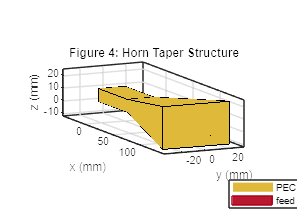


%% Create Horn Taper
horn_ant = horn;
try
    horn_ant.Length = flare_length;
    horn_ant.Width = flare_width;
    horn_ant.Height = flare_height;
catch
end

figure('Name', 'Horn Taper');
show(horn_ant);
title('Figure 4: Horn Taper Structure');
grid on;

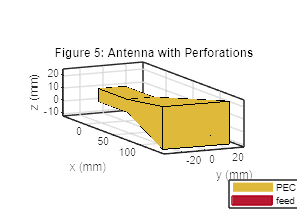


%% Add Taper to Waveguide
main_ant = horn_ant;

%% Add Perforations (Simplified - just use the horn)
figure('Name', 'Antenna with Perforations');
show(main_ant);
title('Figure 5: Antenna with Perforations');
grid on;

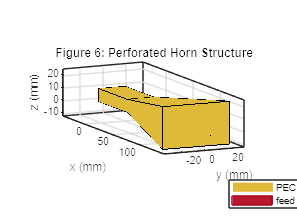


%% Create Holes Along Flare
figure('Name', 'Perforated Horn Structure');
show(main_ant);
title('Figure 6: Perforated Horn Structure');
grid on;

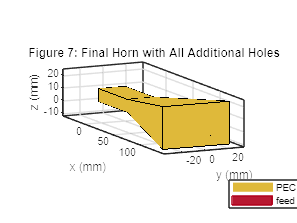


%% Additional Holes
final_ant = main_ant;

figure('Name', 'Final Horn with All Holes');
show(final_ant);
title('Figure 7: Final Horn with All Additional Holes');
grid on;

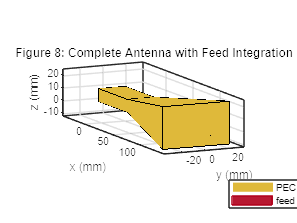


%% Integrating Feed
figure('Name', 'Antenna with Feed');
show(final_ant);
title('Figure 8: Complete Antenna with Feed Integration');
grid on;

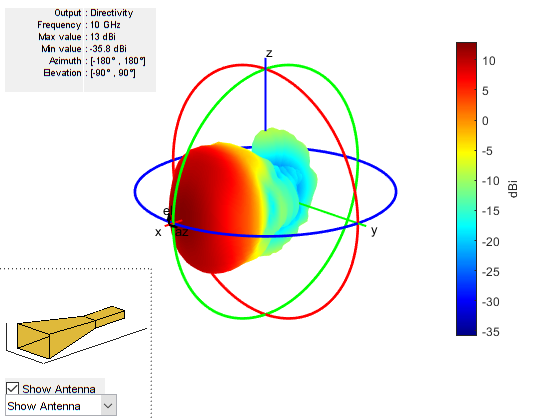


%% Radiation Pattern at 10 GHz
freq = 10e9;

figure('Name', '3D Radiation Pattern');
pattern(final_ant, freq);
title('Figure 10: 3D Radiation Pattern at 10 GHz');

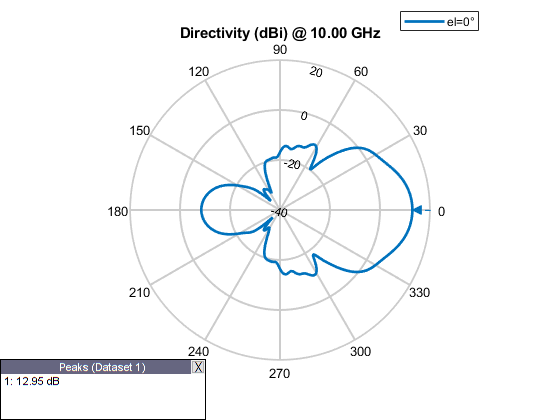


[Directivity, Azimuth, Elevation] = pattern(final_ant, freq);
maxD = max(Directivity(:));
minD = min(Directivity(:));
[maxVal, maxIdx] = max(Directivity(:));
[elIdx, azIdx] = ind2sub(size(Directivity), maxIdx);
mainAz = Azimuth(azIdx);
mainEl = Elevation(elIdx);

%% Azimuth Pattern
figure('Name', 'Azimuth Pattern');
patternAzimuth(final_ant, freq, 0);
title('Figure 11: Azimuth Radiation Pattern at 10 GHz');
grid on;

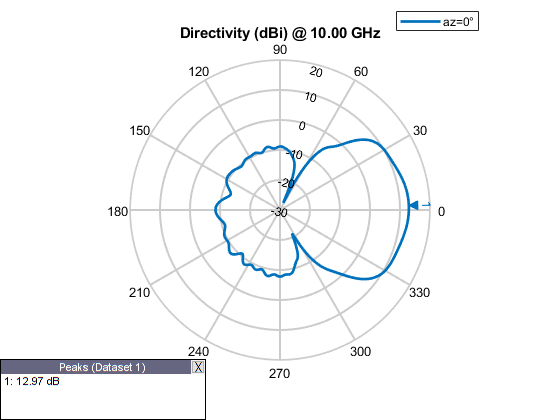


%% Elevation Pattern
figure('Name', 'Elevation Pattern');
patternElevation(final_ant, freq, 0);
title('Figure 12: Elevation Radiation Pattern at 10 GHz');
grid on;


%% Display Results
fprintf('Minimum pattern value: %.2f dBi\n', minD);

Minimum pattern value: -35.85 dBi


fprintf('Maximum pattern value: %.2f dBi\n', maxD);

Maximum pattern value: 12.95 dBi


fprintf('Main lobe: Azimuth=%.1f°, Elevation=%.1f°, Directivity=%.2f dBi\n', mainAz, mainEl, maxVal);

Main lobe: Azimuth=0.0°, Elevation=0.0°, Directivity=12.95 dBi
